clear all;
close all;

% Gaussian Process example
meanfunc = [];                             % empty: don't use a mean function
covfunc = {@covSum,{@covLIN,@covConst}};   % Linear covariance function
likfunc = @likGauss;                       % Gaussian likelihood
hyp = struct('mean', [],'cov', 0, 'lik', -1);

N = 50;
x = rand(N,1);
y = 0.5 * x + 0.5 + 0.1 * randn(size(x));

hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value 2.443337e+00
Function evaluation      8;  Value -4.143410e+01
Function evaluation     10;  Value -4.174437e+01
Function evaluation     13;  Value -4.174879e+01
Function evaluation     16;  Value -4.174897e+01
Function evaluation     19;  Value -4.174898e+01
Function evaluation     22;  Value -4.174898e+01
Function evaluation     26;  Value -4.174898e+01
Function evaluation     30;  Value -4.174898e+01



xs = (0:0.1:1)';
[mu s2] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs);

f1 = [mu + sqrt(s2);flipdim(mu - sqrt(s2),1)];
f2 = [mu + 2 * sqrt(s2);flipdim(mu - 2 * sqrt(s2),1)];

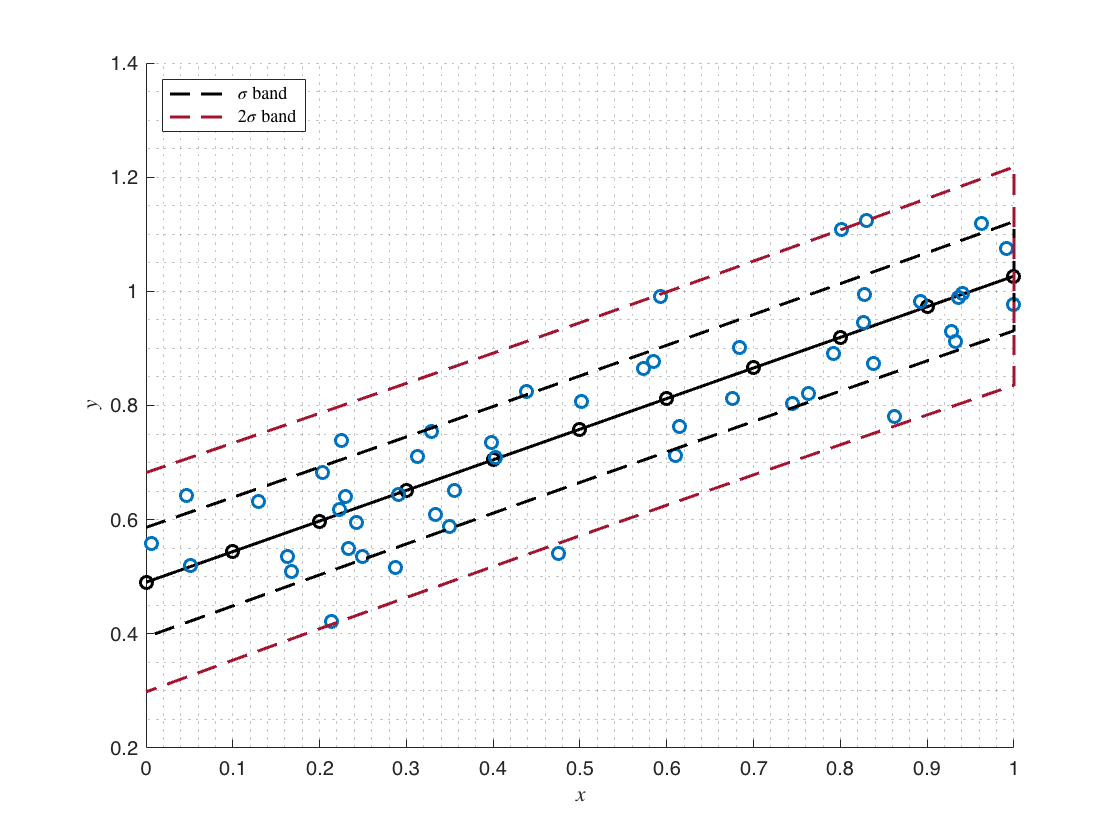

figure(1);hold on

plot(xs, mu,"-o",'linewidth',1.5,'Color','black');      % Plot mid line
plot(x, y,'o','linewidth',1.5,'Color','#0072BD')        % Plot data points

p1 = plot([xs; flipdim(xs,1)],f1,'--','linewidth',1.5,'Color','black');     % Plot σ
p2 = plot([xs; flipdim(xs,1)],f2,'--','linewidth',1.5,'Color','#A2142F');   % Plot 2σ

leg1 = legend([p1 p2],'$\sigma$ band','2$\sigma$ band','Interpreter','latex','Location','northwest');
grid minor
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')